# 1 D SLAB WALL WITH HEAT GENERATION

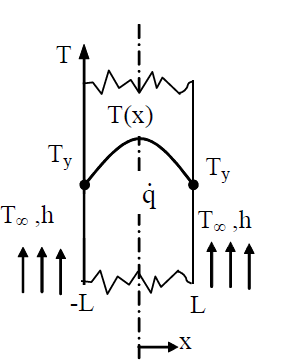

 
$$T\left(x\right)=\frac{qL^2 }{2k}\left(1-\frac{x^2 }{L^2 }\right)+T_0$$


This MATLAB function creates a temperature distribution for parameters L, k, q, T0 and T1.

L is the slab length (m)

k is the thermal conductivity of the wall (W/mK)

q is the heat generation (W/m³)

T0 is the temperature at x=0

T1 is the temperature at x=L

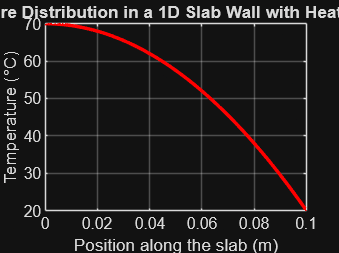

function plotTemperatureDistribution(L, k, q, T0, T1)
    % Parameters
    % L: Length of the slab (m)
    % k: Thermal conductivity (W/m·K)
    % q: Heat generation (W/m^3)
    % T0: Temperature at one end (°C)
    % T1: Temperature at the other end (°C)

    % Define the position along the slab
    x = linspace(0, L, 100); % 100 points from 0 to L

    % Calculate the temperature distribution
    % The general solution for the temperature distribution is:
    % T(x) = T0 + (T1 - T0) * (x / L) + (q / (2 * k)) * (L^2 - x.^2)
    T = T0 + (T1 - T0) * (x / L) + (q / (2 * k)) * (L^2 - x.^2);

    % Plotting the temperature distribution
    figure;
    plot(x, T, 'r', 'LineWidth', 2);
    xlabel('Position along the slab (m)');
    ylabel('Temperature (°C)');
    title('Temperature Distribution in a 1D Slab Wall with Heat Generation');
    grid on;
    xlim([0 L]);
    ylim([min(T) max(T)]);
end

% Example usage
L = 0.1;    % Length of the slab in meters
k = 10;  % Thermal conductivity in W/m·K
q = 100000; % Heat generation in W/m^3
T0 = 20;  % Temperature at one end in °C
T1 = 20;  % Temperature at the other end in °C
plotTemperatureDistribution(L, k, q, T0, T1);